clc;clear;close all;
warning('off','all')

## EXERCISE 3 

1- prove 0, 0 is a fixed point 

syms x y z
fx= f(z)

$$fx = x\,y^{2}-y-x\,z$$

fy=g(z)

$$fy = y^{3}+z\,y+x$$


res= solve([fx == 0, fy == 0], [x, y]);
fprintf('All feasible fixed points depending on the control parameter:')

All feasible fixed points depending on the control parameter:

for i= 1:length(res.x)
    disp([i 'X val' sym2cell(res.x(i)) 'Y val' sym2cell(res.y(i))])
end

    {[1]}    {'X val'}    {[0]}    {'Y val'}    {[0]}

    {[2]}    {'X val'}    {[z*(z^2 - 1)^(1/4) + (z^2 - 1)^(3/4)]}    {'Y val'}    {[-(z^2 - 1)^(1/4)]}

    {[3]}    {'X val'}    {[- z*(z^2 - 1)^(1/4) - (z^2 - 1)^(3/4)]}    {'Y val'}    {[(z^2 - 1)^(1/4)]}

    {[4]}    {'X val'}    {[z*(z^2 - 1)^(1/4)*1i - (z^2 - 1)^(3/4)*1i]}    {'Y val'}    {[-(z^2 - 1)^(1/4)*1i]}

    {[5]}    {'X val'}    {[- z*(z^2 - 1)^(1/4)*1i + (z^2 - 1)^(3/4)*1i]}    {'Y val'}    {[(z^2 - 1)^(1/4)*1i]}



fprintf(['At most 5 possible fixed points, but 0,0 is a fixed point in all of the cases,\n' ...
    'The origin is allways a fixed point for this system for any value of the control parameter.'])

At most 5 possible fixed points, but 0,0 is a fixed point in all of the cases,
The origin is allways a fixed point for this system for any value of the control parameter.


Jacobian_matrix = jacobian([fx, fy], [x, y])

$$Jacobian\_matrix = \left(\begin{array}{cc} y^{2}-z & 2\,x\,y-1\\ 1 & 3\,y^{2}+z \end{array}\right)$$

2- Can it have a hopf bifurcation?

npoints = 0;
newNpoints=0;
differentones=[];

fprintf('Fixed points as parameter changes:')

Fixed points as parameter changes:


for n = -3:0.1:3

    fx= f(n);
    fy=g(n);
    fixed_points = solve([fx == 0, fy == 0], [x, y]);
    x_values = double(fixed_points.x);
    x_values = x_values(x_values==real(x_values));
    npoints=newNpoints;
    newNpoints= length(x_values);
    
    if npoints~= newNpoints
        differentones=[differentones,round(n,2)]; %#ok<*AGROW>
        fprintf('Change of fixed point ammount to %d     when parameter = %1.2f\n', newNpoints, n);
       
    end
    
end

Change of fixed point ammount to 3     when parameter = -3.00
Change of fixed point ammount to 1     when parameter = -1.00
Change of fixed point ammount to 3     when parameter = 1.10


$$eigVal = \left(\begin{array}{c} -\frac{\sqrt{19}\,\mathrm{i}}{10}\\ \frac{\sqrt{19}\,\mathrm{i}}{10} \end{array}\right)$$

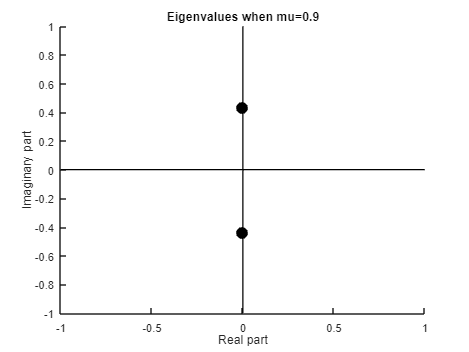

$$eigVal = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

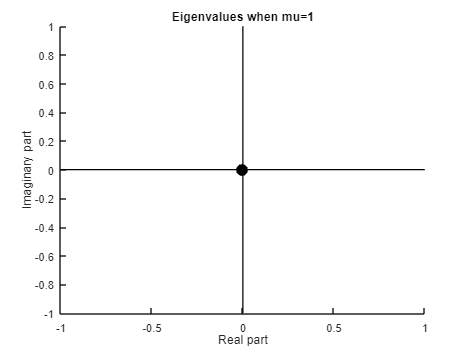

$$eigVal = \left(\begin{array}{c} -\frac{\sqrt{21}}{10}\\ \frac{\sqrt{21}}{10} \end{array}\right)$$

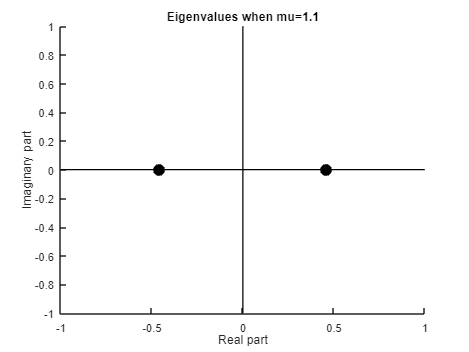

for i = [0.9,1,1.1]
    jp= subs(Jacobian_matrix, [x; y;z], [0;0;i]);
    [eigVec,eigVal] = eig(jp);
    eigVal = diag(eigVal)
    figure
    hold on;
    scatter(real(eigVal),imag(eigVal),100,"black",MarkerFaceColor="black")
    title(['Eigenvalues when mu=' ,num2str(i)])
    line([-1, 1], [0, 0], 'color', 'black');
    line([0, 0], [-1, 1], 'color', 'black');
    xlabel('Real part')
    ylabel('Imaginary part')
    hold off
end

disp('A hopf bifurcation is plausible within said eigenvalue shifts when mu =1')

A hopf bifurcation is plausible within said eigenvalue shifts when mu =1


According to Strogatz, for a Hopf bifurcation to happen   ''we need one or both of the eigenvalues to cross into the  right half-plane as $\mu$ varies.'', which is exactly what we can see when $\mu$ is around 1.

3-represent each qualitatively different case 



----------------------------------------



CASE:

$$fy = x\,y^{2}-y+3\,x$$

$$fx = y^{3}-3\,y+x$$

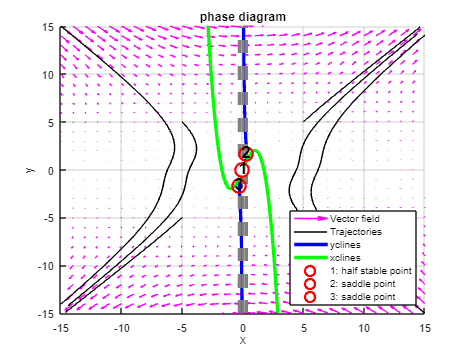



----------------------------------------



CASE:

$$fy = x\,y^{2}-y+x$$

$$fx = y^{3}-y+x$$

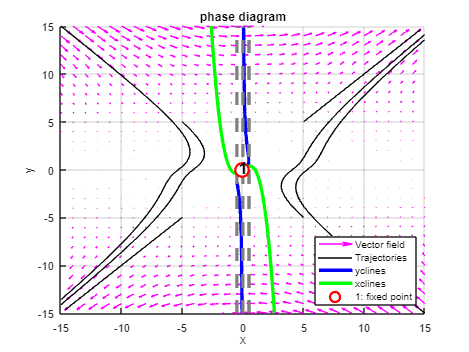



----------------------------------------



CASE:

$$fy = x\,y^{2}-y-\frac{11\,x}{10}$$

$$fx = y^{3}+\frac{11\,y}{10}+x$$

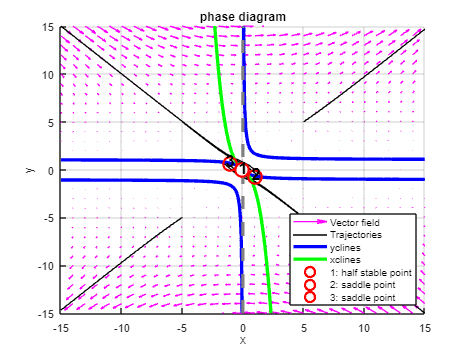

for i = differentones
    fprintf('\n\n----------------------------------------\n\n\n\nCASE:')
    fy=f(i)
    fx= g(i)
    phasediag(fx,fy,[15,15,-15,-15,5,5,-5,-5;15,-15,15,-15,5,-5,5,-5])
end

function fx = f(mu)
    syms x y
    fx= -mu*x-y+x*y^2;
end 
function fy= g(mu)
    syms x y
    fy= x +mu*y+y^3;
end


function phasediag(eq1, eq2,trajectorypoints)
    syms x y
    nullcline_x = solve(eq1 == 0, x);
    nullcline_y = solve(eq2 == 0, y);
    fixedPoints = solve([eq1 == 0, eq2 == 0], [x, y]);
    
    
    figure;
    hold on;
    
    [X, Y] = meshgrid(-15:1:15,-15:1:15);
    U = subs(eq1, [x y], {X,Y});
    V = subs(eq2, [x y], {X,Y});
    quiver(X, Y, U, V,"DisplayName",'Vector field',"Color",'magenta')



    f = matlabFunction([eq1; eq2], 'vars', [x; y]);
   
    tspan = [0, 10]; 
    
    initial_conditions = trajectorypoints;
    

    num_trajectories = size(initial_conditions, 2);
    trajectory_cell = cell(1, num_trajectories);

    for i = 1:num_trajectories
        [~, sol] = ode45(@(t, y) f(y(1), y(2)), tspan, initial_conditions(:, i));
        trajectory_cell{i} = sol;
    end
    
    
    for i = 1:num_trajectories
        x_trajectory = trajectory_cell{i}(:, 1);
        y_trajectory = trajectory_cell{i}(:, 2);
        if i == 1
            plot(x_trajectory, y_trajectory,Color='black',DisplayName='Trajectories');
        else
            plot(x_trajectory, y_trajectory,Color='black',HandleVisibility='off');
        end
    end
    for i = 1:length(nullcline_y)
        if i == 1
            fplot(nullcline_y(i),Color='blue',DisplayName='yclines',LineWidth=3)
        else
            fplot(nullcline_y(i),Color='blue',LineWidth=3, HandleVisibility='off')
        end
    end

    for i = 1:length(nullcline_x)
        if i == 1
            fplot(nullcline_x(i),Color='g',DisplayName='xclines',LineWidth=3)
        else
            fplot(nullcline_x(i),Color='g',LineWidth=3, HandleVisibility='off')
        end
    end
    
    grid on

    xlim([-15,15])
    ylim([-15,15])
    Jacobian_matrix = jacobian([eq1, eq2], [x, y]);
    for i = 1:length(fixedPoints.x)
        xv= double(fixedPoints.x(i));
        yv= double(fixedPoints.y(i));
        if isreal([xv,yv])
           J_at_point = subs(Jacobian_matrix, [x; y], [xv;yv]);
        
           tr= trace(J_at_point);
           dete= det(J_at_point);
           parab = tr^2-4*dete;
           
           if dete < 0
               str = i + ": saddle point";
               plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str);
               
           elseif dete > 0
               if tr < 0
                str = i + ": stable point";
                plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str,MarkerFaceColor='red');
               elseif tr> 0
                str = i + ": unstable point";
                plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str,MarkerFaceColor='white');    
               else
                str = i + ": half stable point";
                plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str,MarkerFaceColor='white');  
               end
           elseif dete == 0
               if parab > 0
                str = i + ": non isolated stable point";
                plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str,MarkerFaceColor='red');
               elseif parab < 0
                str = i + ": non isolated unstable point";
                plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str,MarkerFaceColor='white');
               else
                str = i + ": fixed point";
                plot(xv, yv, 'ro', 'MarkerSize', 12, 'LineWidth', 2,DisplayName=str,MarkerFaceColor='white');

               end
           end
           text(xv,yv,"\bf"+int2str(i),"FontSize",15,HorizontalAlignment="center")
        end
    end
    title('phase diagram')
    xlabel('x')
    ylabel('y')
    legend(Location="southeast")
   
    hold off;

end

